%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Demo.mlx
% This live script demonstrates some of the features of the 
% MATLAB toolbox for accessing and visualizing BGC-Argo float data.
%
% AUTHORS: 
%   J. Sharp, H. Frenzel, A. Fassbender (NOAA-PMEL), N. Buzby (UW),
%   J. Plant, T. Maurer, Y. Takeshita (MBARI), D. Nicholson (WHOI),
%   and A. Gray (UW)
%
% CITATION:
%   H. Frenzel*, J. Sharp*, A. Fassbender, N. Buzby, J. Plant, T. Maurer,
%   Y. Takeshita, D. Nicholson, A. Gray, 2021. BGC-Argo-Mat: A MATLAB
%   toolbox for accessing and visualizing Biogeochemical Argo data.
%   Zenodo. https://doi.org/10.5281/zenodo.4971318.
%   (*These authors contributed equally to the code.)
%
% LICENSE: bgc_argo_mat_license.m
%
% DATE: FEBRUARY 22, 2022  (Version 1.2)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

global Settings;

## Hawaii floats

In this exercise, we define a region near Hawaii using latitude and longitude limits along with a duration of time using date limits (year/month/day). First we identify the float profiles matching those criteria, then we show various ways of plotting the data.

## Set limits near Hawaii from 2017 to 2019

latlim=[22 26];
lonlim=[-160 -155];
t1=[2017 1 1];
t2=[2019 12 31];

## Select floats and profiles based on those limits

With this command, we get the WMO IDs of all profiles that match the geographical and temporal limits. 

Included are all floats that have at least one profile that matches the criteria. 

The second return value of the select_profiles function is a cell array that specifies the indices of the matching profiles for each float.

All necessary initializations are performed during the execution of the select_profiles function, and the Sprof files for all matching floats are downloaded from the GDAC. Whenever possible (i.e., when enough good location data are available), missing locations are interpolated to make sure that no floats or profiles are missed. The informational messages can be suppressed by setting the value of Settings.verbose to 0 in function initialize_argo.m

[HW_floats,HW_float_profs] = select_profiles(lonlim,latlim,t1,t2,...
    'outside','none'); % exclude profiles outside the time and space limits

Sprof index file will now be downloaded.
Depending on your internet connection, this may take a while.
Attempting download of https://usgodae.org/ftp/outgoing/argo/argo_synthetic-profile_index.txt.gz
to ./Index/argo_synthetic-profile_index.txt.gz ... success!
meta index file will now be downloaded.
Attempting download of https://usgodae.org/ftp/outgoing/argo/ar_index_global_meta.txt
to ./Index/ar_index_global_meta.txt ... success!
position interpolation performed for 2 missing values of float 2902178
position interpolation performed for 4 missing values of float 2902189
position interpolation performed for 1 missing values of float 2902193
position interpolation performed for 4 missing values of float 2902196
position interpolation performed for 2 missing values of float 2902199
position interpolation performed for 2 missing values of float 2902202
position interpolation performed for 1 missing values of float 2902205
position interpolation performed for 2 missing values of float 29022

## **Display the number of matching floats and profiles**

disp(['# of matching profiles: ' num2str(sum(cellfun('length',...
    HW_float_profs)))]);

# of matching profiles: 252


disp(['# of matching floats: ' num2str(length(HW_floats))]);

# of matching floats: 5


## Show trajectories for the matching floats, along with the geographic limits

This function loads the data for plotting. Adding the optional input pair 'color','multiple' will plot different floats in different colors. A black rectangle is superimposed to show the geographic limits we specified above. 

All floats have some profiles within the specified region and many more outside of it.

show_trajectories(HW_floats,'color','multiple');

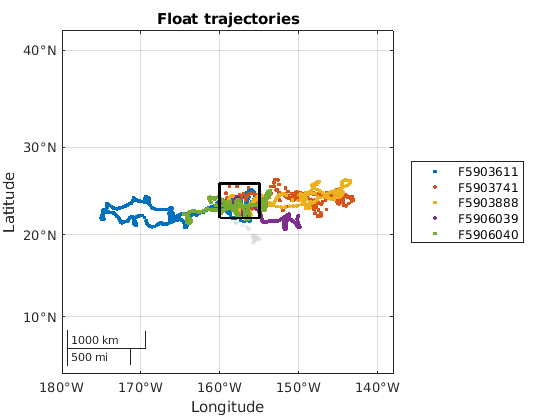

hold on;

% show geographic limits (the mapping function used depends on Settings)
if strcmp(Settings.mapping, 'native')
    geoplot([latlim(1) latlim(2) latlim(2) latlim(1) latlim(1)],...
        [lonlim(1) lonlim(1) lonlim(2) lonlim(2) lonlim(1)],...
        'k','linewidth',2);
elseif strcmp(Settings.mapping, 'm_map')
    m_plot([lonlim(1) lonlim(1) lonlim(2) lonlim(2) lonlim(1)],...
        [latlim(1) latlim(2) latlim(2) latlim(1) latlim(1)],...
        'k','linewidth',2);
else
    plot([lonlim(1) lonlim(1) lonlim(2) lonlim(2) lonlim(1)],...
        [latlim(1) latlim(2) latlim(2) latlim(1) latlim(1)],...
        'k','linewidth',2);
end
hold off;

## Show trajectories for the matching profiles from each float, along with the geographic limits

Adding the optional input of 'float_profs' with the per-float profile numbers returned by the select_profiles function will plot only the locations of those profiles from the specified floats that lie within the limits.

The specified region is shown again with a black rectangle to demonstrate this.

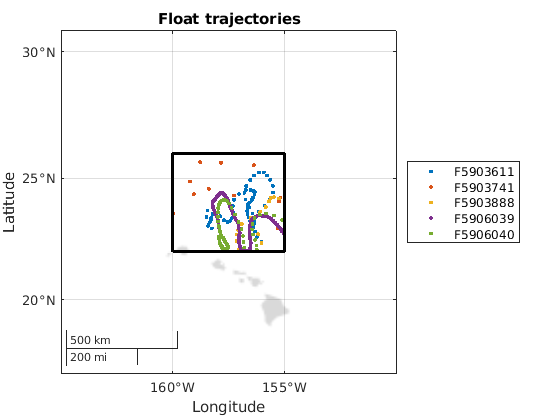

show_trajectories(HW_floats,'color','multiple','float_profs',HW_float_profs);
hold on;

% show geographic limits (the mapping function used depends on Settings)
if strcmp(Settings.mapping, 'native')
    geoplot([latlim(1) latlim(2) latlim(2) latlim(1) latlim(1)],...
        [lonlim(1) lonlim(1) lonlim(2) lonlim(2) lonlim(1)],...
        'k','linewidth',2);
elseif strcmp(Settings.mapping, 'm_map')
    m_plot([lonlim(1) lonlim(1) lonlim(2) lonlim(2) lonlim(1)],...
        [latlim(1) latlim(2) latlim(2) latlim(1) latlim(1)],...
        'k','linewidth',2);
else
    plot([lonlim(1) lonlim(1) lonlim(2) lonlim(2) lonlim(1)],...
        [latlim(1) latlim(2) latlim(2) latlim(1) latlim(1)],...
        'k','linewidth',2);
end
hold off;

## Show matching profiles from all floats

Here we show profiles from all floats for salinity (PSAL) and dissolved oxygen (DOXY) within the specified domain and time. The mean value across all profiles is plotted in black.

Only good (QC flag 1) and probably good (QC flag 2) values are plotted. The values are adjusted (either real-time or delayed mode). Raw values can be shown by adding options 'raw','yes' in the function call.

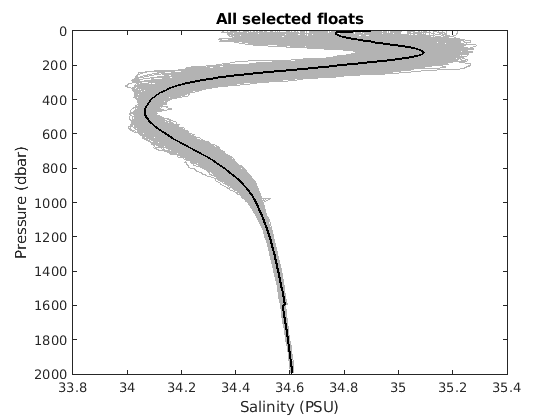

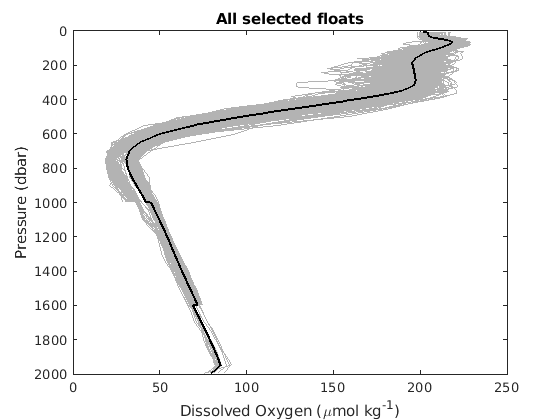

show_profiles(HW_floats, {'PSAL';'DOXY'},'float_profs',HW_float_profs,...
    'per_float',0,... % tells the function to show data from all floats in a single plot (one per specified variable)
    'qc',[1 2]);  % tells the function to plot good and probably-good data

## Show sections for pH and oxygen for the fifth float

These figures show vertical sections along the float track for the adjusted data of pH (PH_IN_SITU_TOTAL) and oxygen (DOXY) for one of the floats near Hawaii. The sampling locations are shown with small black dots. Isopycnal lines (for sigma=24, 25, 26, and 27) are shown with thin black lines. Mixed layer depth is shown with a thick black line; it is based on the temperature threshold (set the value to 2 after 'mld' in the function options to use the density threshold instead).

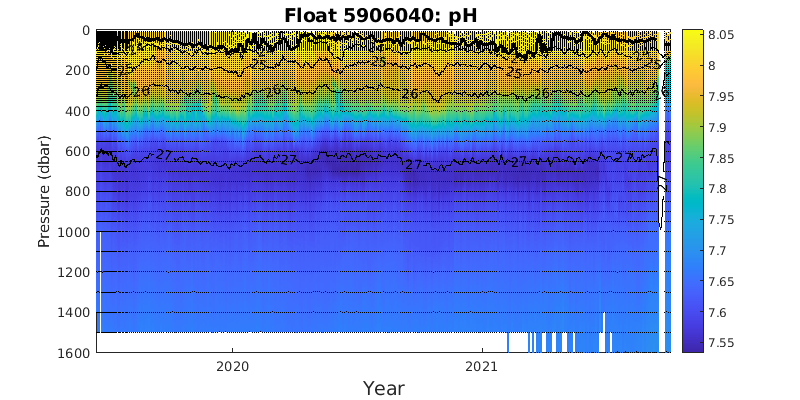

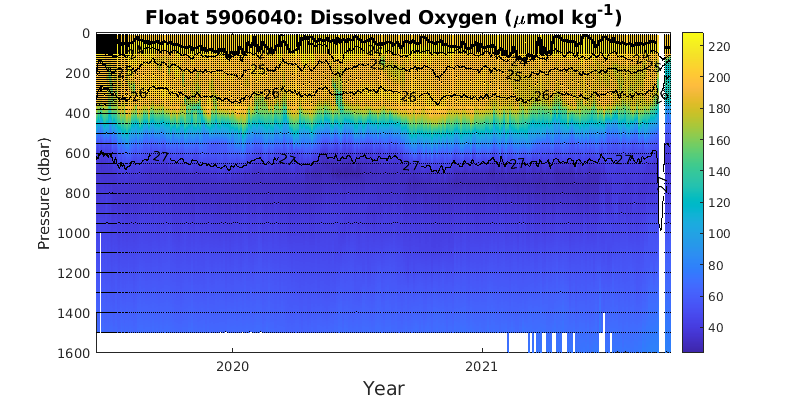

show_sections(HW_floats(5), {'PH_IN_SITU_TOTAL';'DOXY'}, 'mld', 1);

## Show time series of near-surface pH and oxygen for two floats

These figures display pH values and oxygen concentrations at a depth of 20 dbar for two of the floats near Hawaii in one plot per variable. Adjusted values are used.

The pH sensor for float 5906039 failed in late 2019, which is evident from the premature end to the blue line halfway through the first figure.

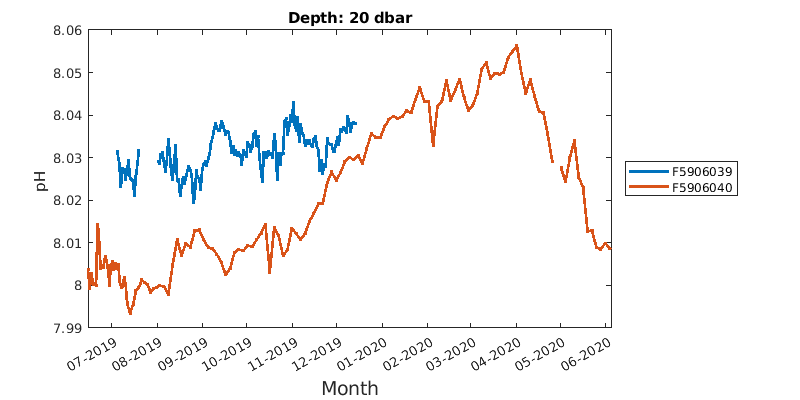

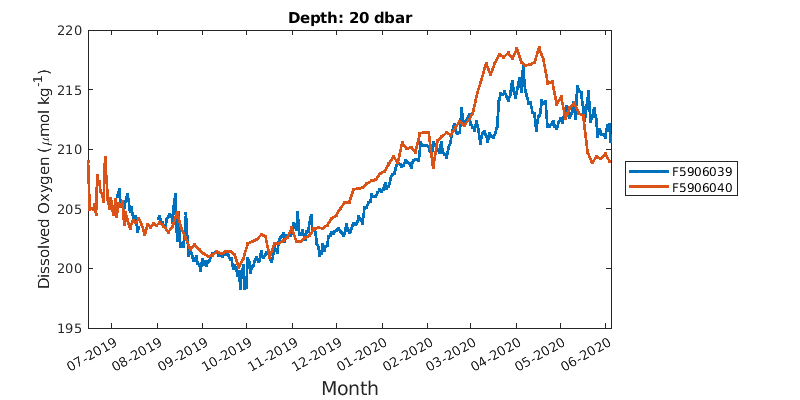

show_timeseries(HW_floats(4:5), {'PH_IN_SITU_TOTAL';'DOXY'}, 20, ...
    'per_float', 0); % tells the function to show data from all floats in a single plot (one per specified variable)